# Ejemplos de robot y cinta trasportadora

Dificultad: Normal (Ejemplos)

clear all
close all


## Introducción

- Se diseña una cinta trasportadora con un eje prismático.

- Se acopla un robot a una cinta trasportadora consiguiendo un robot hiper-redundante, con $7$ grados de libertad.

## Cinta transportadora

- La cinta transportadora es un robot con un eje prismático que mueve una pieza.

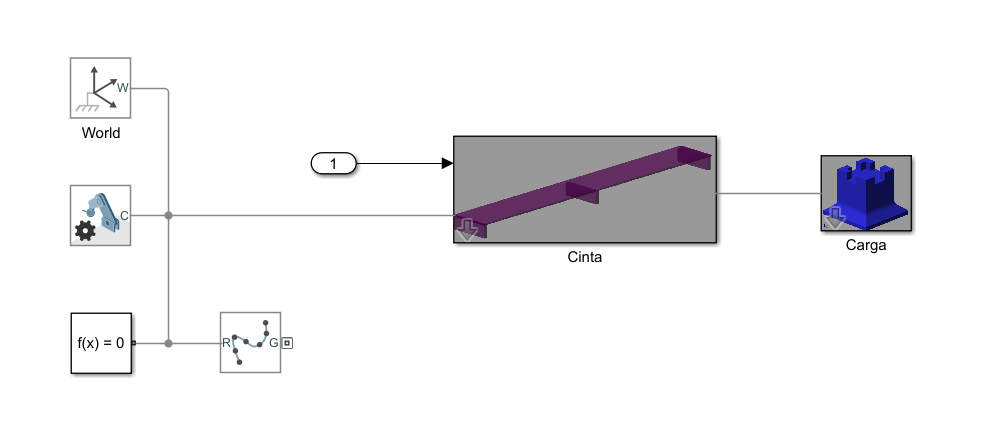

clear all
deg= pi/180;

Estacion= 'C21S1_Cinta_Transportadora.slx';
% Variables de simulink

% Posición inicial del robot y del rastreador
q0_= zeros(1,1);
pose_= randn(3,3)*1e-3;

% Posición de la cinta
baseCinta= zeros(1,6);


% Tool load y wobj Se genera una variable estructura de nombre tool1

% Torre (icono variable)
Carga= Pieza('Torre');
Carga.Base([[0,0,0]*1e-3, [0,0,90]*deg]);
Carga.Tcp([[0,0,50]*1e-3,[0,0,180]*deg]);
Carga.Color([0.4,0,0.4,0.7]);

% Abrir estación
open_system(Estacion)
robot= importrobot(Estacion);
robot.showdetails

--------------------
Robot: (3 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1         fixed             Base(0)   Body2(2)  
   2        Body2        Joint2     prismatic            Body1(1)   Body3(3)  
   3        Body3        Joint3         fixed            Body2(2)   
--------------------


TcpCinta= 'Body2';
q0= 0;
rob= Cin(robot, Estacion, TcpCinta, q0);

Herramienta: Body2
Simulación. Ts= 0.100 m/s


## Movimiento en cinta

- El movimiento simula el desplazamiento de la torre en la cinta transportadora.

rob.MoveAbsJ(500*1e-3);

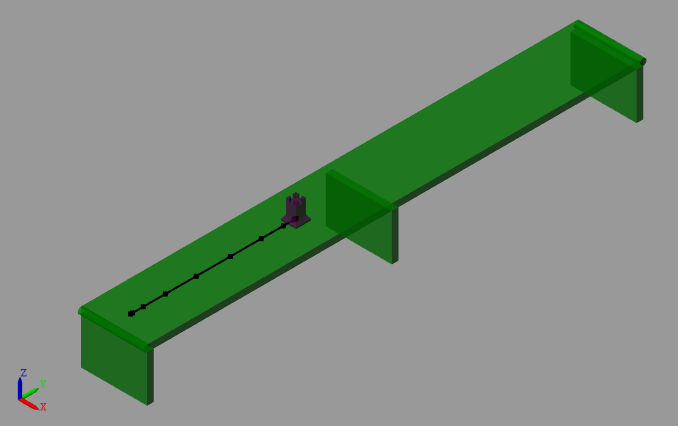

## Robot sobre pinza transportadora

- Se coloca el robot sobre la cinta transportadora.

- El robot es ahora un robot hiper-redundante, ya que tiene 7 grados de libertad.

- Los movimientos del robot se harán usando los 7 grados de libertad.

#### Posición inicial del robot

- Se debe posicionar el robot encima de la cinta con la orientación correspondiente.

- Las articulaciones prismáticas y rotacionales se mueven respecto del eje $z$, por lo que este movimiento no es obvio.

#### Definir las articulaciones de cada robot y conectar las entradas correspondientes a cada uno 

- Un grave problema es determinar en el objeto *RigidBody* cuáles son las articulaciones de la cinta y del robot. No está claro el orden en el que se compila las mismas, es preciso verlo en el esquema.

- En este caso el *Body02* es el eje prismático de la cinta, y el resto de ejes rotacionales pertenen al robot.

- Eso implica que la primera señal será para la cinta y el resto para el robot.

- Las variables internas $q0\_$, tiene $7$ elementos, de los cuales $q0\_(1)$ pertenece a la cinta y el resto $q0\_(2:7)$ al robot. Ver en los iconos de uno y otro.

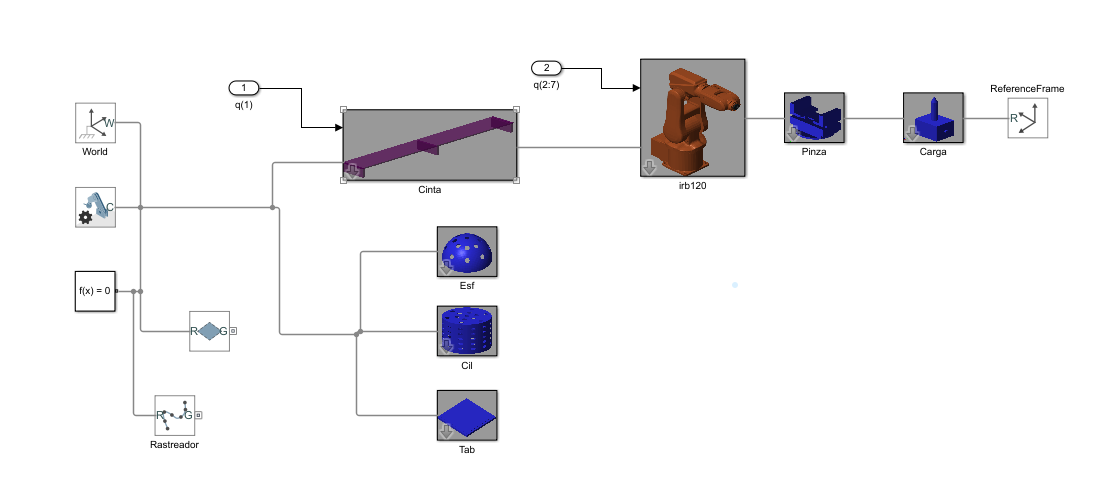

## Iconos *subsystem*

- Los elementos dinámicos, eje y robots, pueden ser guardados en un archivo subsystem. 

- En nuestra estación podemos llamar a un archivo *subsystem* de forma similar a llamar a una función en la programación convencional.

- Con ello podemos cambiar fácilmente de robot, sin más que llamar a otro fichero* subsystem*.

- Los ficheros *subsystem* tiene máscara para obtener los parámetros necesarios para su simulación.

- Hay problemas con la posición de las entradas y salidas en el icono subsystem, que no siempre se sitúan en la misma posición.

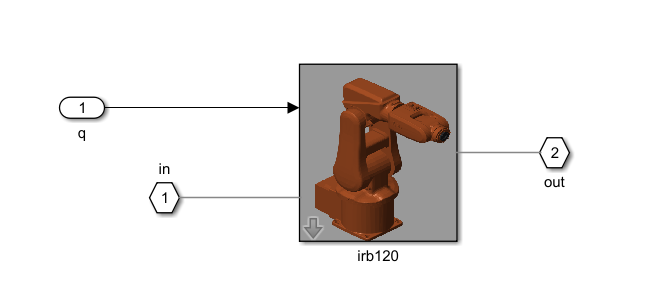

clear all
deg= pi/180;

Estacion=  'C21S2_Robot_sobre_Cinta.slx';
% Se inicia la clase con el robot con el interface de simulink
% VER VERSIÓN SIMULINK
% Variables de simulink

% Posición inicial del robot y del rastreador
% Estas variables van a ser usadas por los objetos Cin como variables del sistema 
% No deben modificarse en el programa 
q0_= zeros(1,7);
pose_= randn(3,3)*1e-3;

% Posición de la base del robot y la cinta transportadora
baseCinta= [[0,0,140]*1e-3,[0,0,0]*deg];
baseRobot= [[0,0,100]*1e-3, [0,-90,90]*deg];

% Tool load y wobj Se genera una variable estructura de nombre tool1

% Icono variable
Pinza= Pieza('Pinza_Completa');
Pinza.Base([[0,0,0]*1e-3, [90,0,0]*deg]);
Pinza.Tcp([[0,0,70]*1e-3, [0,0,0]*deg]);
Pinza.Color([0.4,0,0.4,0.7]);

% Icono variable
Carga= Pieza('Lapiz');
Carga.Tcp([[0,0,148]*1e-3, [0,0,0]*deg]);
Carga.Color([0,0.4,0.4,0.7]);

% Esfera (icono constante)
Esf= Pieza('Esfera');
Esf.Base([[500, 600,0]*1e-3, [0,0,0]*deg]);
Esf.Color([0,0.3,0.8,0.7]);

% Cilindro (icono constante)
Cil= Pieza('Cilindro');
Cil.Base([[700, 900, 400]*1e-3, [0, 0, 0]*deg]);
Cil.Color([0.4,0.7,0.2,0.7]);


--------------------
Robot: (13 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        Body01        Joint01          fixed              Base(0)   Body02(2)  
   2        Body02        Joint02      prismatic            Body01(1)   Body03(3)  
   3        Body03        Joint03          fixed            Body02(2)   Body04(4)  
   4        Body04        Joint04          fixed            Body03(3)   Body05(5)  
   5        Body05        Joint05       revolute            Body04(4)   Body06(6)  
   6        Body06        Joint06       revolute            Body05(5)   Body07(7)  
   7        Body07        Joint07       revolute            Body06(6)   Body08(8)  
   8        Body08        Joint08       revolute            Body07(7)   Body09(9)  
   9        Body09        Joint09       revolute            Body08(8)   Body10(10)  
  10        Body10      

% Tablero (icono constante)
Tab= Pieza('Tablero');
Tab.Base([[-400, 200, 200]*1e-3, [-90, 0, -30]*deg]);
Tab.Color([0.2,0.5,0.1,0.7])

% Abrir
open_system(Estacion)

Herramienta: Body13
Simulación. Ts= 0.100 m/s



robot= importrobot(Estacion);
robot.showdetails
TcpCinta= 'Body2';
TcpCarga= 'Body13';
TcpPinza= 'Body12';
q0_= zeros(1,7);
q0= zeros(1,7);

rob= Cin(robot, Estacion, TcpCarga, q0);


## Movimientos por ejes de la cinta-robot

- Movimiento en cinemática directa.

deg= pi/180;

JacIK activado

rob.Rec
ejeC= 500*1e-3;
ejeR= [0,0,0,0,90,0]*deg;
rob.MoveAbsJ([ejeC,ejeR]);


## Movimientos por puntos absolutos y relativos

- Movimientos a puntos absolutos y relativos usando los 7 grados de libertad.

% Podemos modificar el método de IK
rob.JacIK(0.6)



rob.MoveAbsJ([ejeC,ejeR]);
punto= [[-200,200,200]*1e-3,[0,0,180]*deg];
rob.MoveJ(punto);


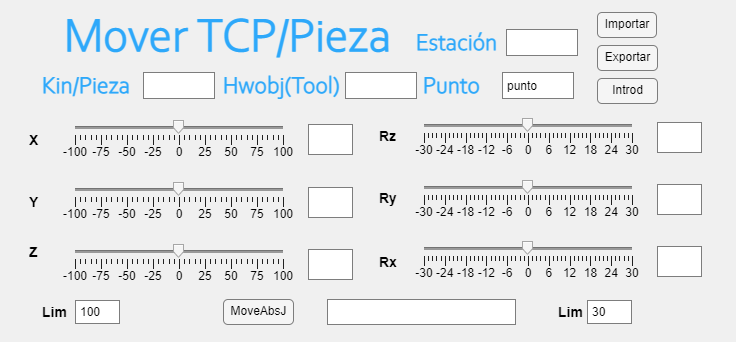

% Movimiento articular y cartesiano
%rob.Rec
ejeC= 100*1e-3;

ejeR= [0,0,0,0,90,0]*deg;
rob.MoveAbsJ([ejeC,ejeR]);
punto= [[0,0,200]*1e-3,[0,0,180]*deg];
rob.MoveJ(punto, Esf);
%rob.Rep

## 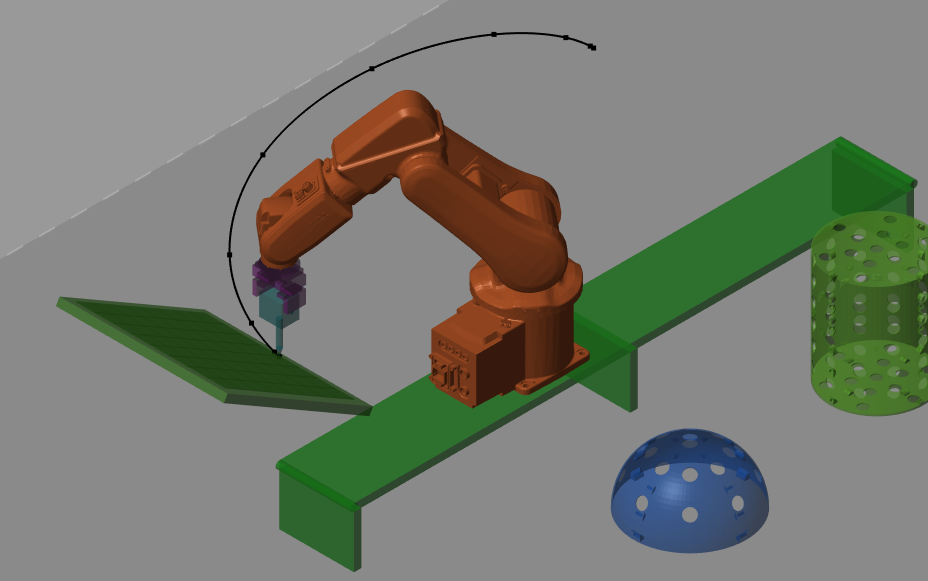

## Mover con la appMover

appMover